N = length(Accel);
t = linspace(0,N / 100.0,N)';
Accel = Accel - Accel(1,:)

Accel =          0         0         0
    0.0048   -0.0287    0.0096
    0.0120   -0.0287    0.0335
    0.0192   -0.0191    0.0167
    0.0144   -0.0048    0.0024
    0.0359    0.0120    0.0263
    0.0311    0.0407    0.0311
    0.0239    0.0526    0.0431
    0.0192    0.0455    0.0431
    0.0072    0.0335    0.0335


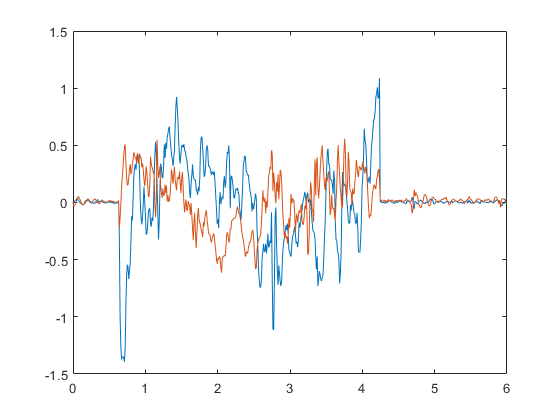

plot(t,Accel(:,1))
hold on
plot(t,Accel(:,2))
hold off

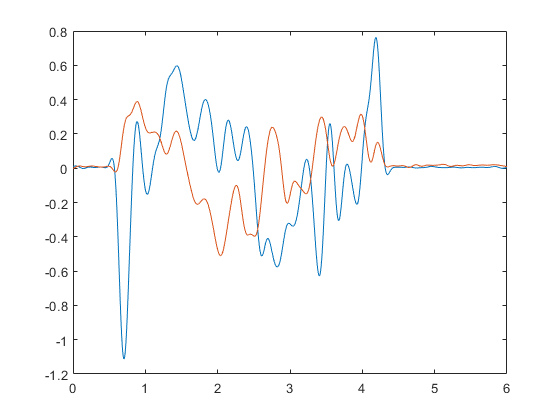

filtAccel = lowpass(Accel,1,Fs);
plot(t,filtAccel(:,1))
hold on
plot(t,filtAccel(:,2))
hold off

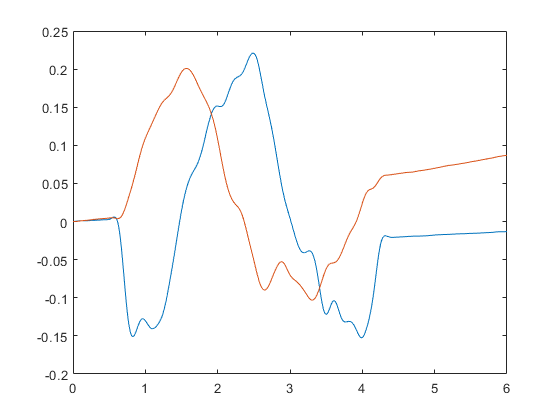

velx = cumtrapz(t,filtAccel(:,1));
vely = cumtrapz(t,filtAccel(:,2));
plot(t,velx)
hold on
plot(t,vely)
hold off

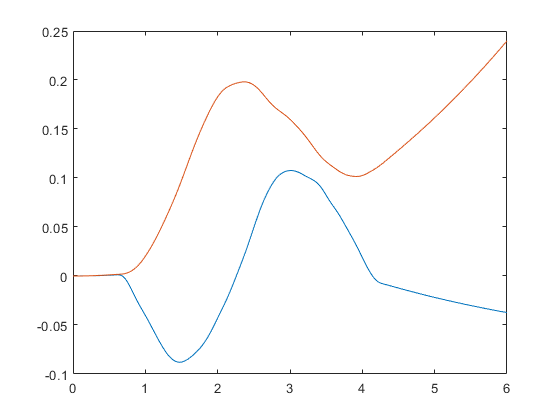

posx = cumtrapz(t,velx);
posy = cumtrapz(t,vely);
plot(t,posx)
hold on
plot(t,posy)
hold off

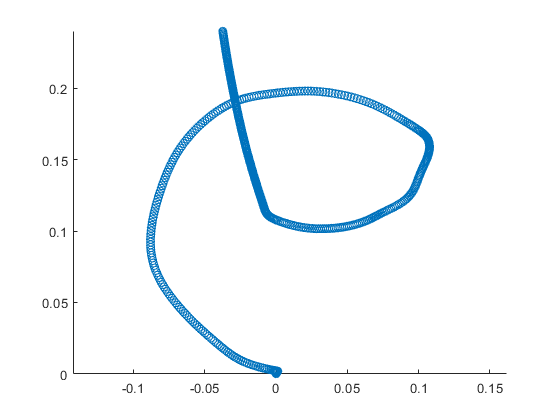

scatter(posx,posy)
axis equal